# Homework 4 (Solutions)

Math 3607, Spring 2022

Tae Eun Kim

## Problem 1 (Sliders in grooves)

(a)

Using trigonometry, we find that

$\left\{ \;
\begin{array}{rcl}
x & = & L \cos \theta \\
y & = & (L-\ell) \sin \theta
\end{array}
\right.
\qquad \theta \in [0, 2\pi)$.

We recognize it as a parametric representation of an ellipse

$\frac{x^2}{L^2} + \frac{y^2}{(L-\ell)^2} = 1$.

(b) The parametric equations are more convenient for plotting the trajectory of $C$: 

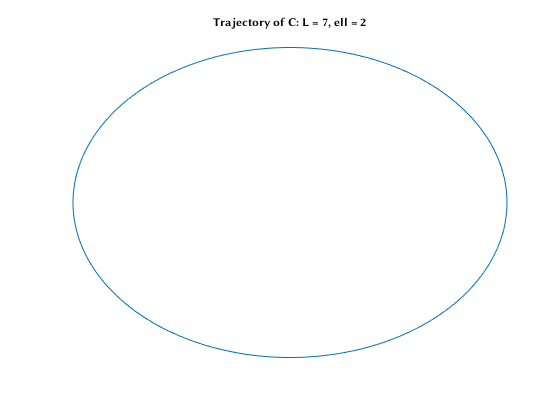

L = 7; 
ell = 2;
theta = linspace(0, 2*pi, 361);
x = L*cos(theta);
y = (L-ell)*sin(theta);
clf, plot(x,y), axis equal, axis off
str = sprintf('Trajectory of C: L = %d, ell = %d', L, ell);
title(str)

**Note.** See how the title string `str` was defined using `sprintf` which is very similar to `fprintf`.

## Problem 2 (Spiral polygons)

(a) The modified code (as a function) is included at the end of this document under **Functions Used**.

(b) Running the given statements:

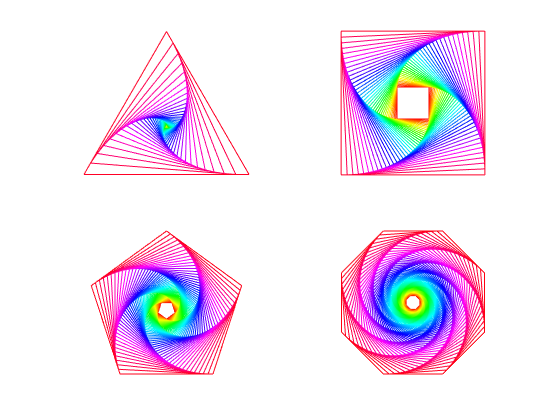

 clf
 subplot(2, 2, 1), spiralgon(3, 41, 4.5, -90);
 subplot(2, 2, 2), spiralgon(4, 37, -2.5, 45);
 subplot(2, 2, 3), spiralgon(5, 61, 3, -90);
 subplot(2, 2, 4), spiralgon(8, 91, -4, 22.5);

## Problem 3 (Machine epsilon)

format long g

(a) Successor of 8:

(8 + 4*eps) - 8

ans =      0

(8 + 4.01*eps) - 8

ans =       1.77635683940025e-15

Observe that the gap between `8 + 4.01*eps` and `8 `is not `4.01*eps`, but rather `8*eps.`

8*eps

ans =       1.77635683940025e-15

(b) Predecessor of 16:

16 - (16 - 4.01*eps)

ans =       1.77635683940025e-15

16 - (16 - 4*eps)

ans =      0

Note that `16 - 4*eps` is registered to be the same as `16` in MATLAB while `16 - 4.01*eps` is rounded down to `16 - 8*eps`. This is how we know that `16 - 8*eps` comes immediately before `16` on the floating-point number system. 

(c) Neighbors of $2^{10}$:

The gap between $2^{10}$ and the next floating-point number is $2^{10}  \cdot {\tt eps} = 2^{-42}$.

(2^10 + 2^9*eps) - 2^10

ans =      0

(2^10 + (2^9+1)*eps) - 2^10

ans =       2.27373675443232e-13

2^(-42)

ans =       2.27373675443232e-13

The gap between $2^{10}$ and the one before is $2^{9} \cdot {\tt eps} = 2^{-43}$.

2^10 - (2^10 - 2^8*eps)

ans =      0

2^10 - (2^10 - (2^8+1)*eps)

ans =       1.13686837721616e-13

2^(-43)

ans =       1.13686837721616e-13

## Problem 4 (Catastrophic cancellation)

(a) From the Maclaurin series (that is, the Taylor series centered at 0) expansion of $e^x$

      
$$e^x = 1 + x + \frac{1}{2} x^2 + \cdots = \sum_{j=0}^{\infty} \frac{x^j}{j!},$$


it follows that


$$\begin{array}{rcl}
  \lim_{x \to 0} f(x)
  & = & \lim_{x \to 0} \frac{(1 + x + x^2/2 + x^3/6 + \cdots) - 1}{x} \\
  & = & \lim_{x \to 0} \frac{x + x^2/2 + x^3/6 + \cdots }{x} \\
  & = & \lim_{x \to 0} \left( 1 + \frac{1}{2} x + \frac{1}{6} x^2 + \cdots \right) = 1.
  % = & \lim_{x \to 0} \frac{\sum_{j=1}^\infty x^j / j!}{x} = \lim_{x \to 0} \sum_{j=1}^{\infty} \frac{x^{j-1}}{j!} = 1.
\end{array}
$$


This shows that $\lim_{x\to 0} f(x) = f(0)$, that is, $f$ is continuous at $0$.

(b) In what follows, note the use of the elementwise division `./`. Also recall that $\log$, in this class and in MATLAB, denotes the natural logarithmic function. Lastly, pay attention to the vectorization (no use of a loop).

k = [1:20]';
x = 10.^(-k);
fx = (exp(x) - 1)./x;            %   (i)   f(x)
f1x = (exp(x) - 1)./log(exp(x)); %  (ii) f_1(x)
f2x = expm1(x)./x;               % (iii) f_2(x)
format long e
disp([x fx f1x f2x])             % or use fprintf to suit your taste

     1.000000000000000e-01     1.051709180756477e+00     1.051709180756476e+00     1.051709180756476e+00
     1.000000000000000e-02     1.005016708416795e+00     1.005016708416806e+00     1.005016708416806e+00
     1.000000000000000e-03     1.000500166708385e+00     1.000500166708342e+00     1.000500166708342e+00
     1.000000000000000e-04     1.000050001667141e+00     1.000050001666708e+00     1.000050001666708e+00
     9.999999999999999e-06     1.000005000006965e+00     1.000005000016667e+00     1.000005000016667e+00
     1.000000000000000e-06     1.000000499962184e+00     1.000000500000167e+00     1.000000500000167e+00
     1.000000000000000e-07     1.000000049433680e+00     1.000000050000002e+00     1.000000050000002e+00
     1.000000000000000e-08     9.999999939225290e-01     1.000000005000000e+00     1.000000005000000e+00
     1.000000000000000e-09     1.000000082740371e+00     1.000000000500000e+00     1.000000000500000e+00
     1.000000000000000e-10     1.000000082740371e+00   

(c) For small $x$, the evaluation of the expression $y = e^x - 1$ suffers from catastrophic cancellation because $e^x \approx 1$. This explains why the numerical evaluation of $f(x)$ is inaccurate for small $x$. To understand why $f_1(x)$ is doing better, denote by $\hat{y}$ the floating-point representation of the numerator $y = e^x - 1$. As mentioned above, due to catastrophic cancellation, many significant digits are lost in $\hat{y}$ for small $x$.

Now, the Taylor expansion for the denominator $\log e^x = \log( 1 + (e^x - 1)) = \log(1 + y)$, written in terms of $y$, is


$$\log e^x = y - \frac{1}{2} y^2 + \frac{1}{3} y^3 - \cdots,$$


and so its numerical evaluation can be approximated by


$$\widehat{ \log e^x } = \hat{y} - \frac{1}{2} \hat{y}^2 + \frac{1}{3} \hat{y}^3 - \cdots,$$


which involves an error as well. Nonetheless, when both are put together,


$$\begin{array}{rcl}
  \underbrace{\frac{e^x - 1}{\log e^x}}_{\text{analytical}}
  & \approx & \frac{\hat{y}}{\hat{y} - \hat{y}^2/2 + \hat{y}^3/3 - \cdots} \\
  & = & \underbrace{1 + \text{(tiny higher-order terms)}}_{\text{numerical}}.
\end{array}$$


yielding the correct asymptotic behavior for small $y$, in turn, for small $x$. This explains why $f_1(x)$ results in plausible results until when the evaluation of $y$ loses all the significant digits, *i.e.*, when $\hat{y} = 0$. In the script above, this happens when $k = 16$, at which point $\widehat{\log e^x} = 0$, *i.e.*, the denominator also evaluates to 0, resulting in `NaN`.

The `expm1` function was designed to avoid catastrophic cancellation in the calculation of $e^x - 1$ for small $x$; the name comes from  $e^x - 1$ (`exp` of $x$ `m`inus `1`). 

help expm1

 expm1  Compute EXP(X)-1 accurately.
     expm1(X) computes EXP(X)-1, compensating for the roundoff in EXP(X).
 
     For small real X, expm1(X) should be approximately X, whereas the
     computed value of EXP(X)-1 can be zero or have high relative error.
 
     See also exp, log1p.

    Documentation for expm1



Hence, $f_2(x)$ is evaluated to the full double-precision for all $x$ values used.

## Problem 5 (Inverting hyperbolic cosine)

t = -4:-4:-16;
x = cosh(t);

(a) Let $f(x) = \log(x - \sqrt{x^2-1}) = \text{acosh}(x)$. Calculation shows that

$\kappa_f (x) = \left| \frac{xf'(x)}{f(x)} \right| = \left| \frac{x}{\sqrt{x^2-1}} \cdot \frac{1}{\log (x - \sqrt{x^2-1})} \right|$.

We evaluate the condition number at the entries of `x`, all at once, by

f  = log(x - sqrt(x.^2-1));
fp = -1./sqrt(x.^2-1);
kappa = abs( x.*fp./f )

kappa =      2.501677876004177e-01     1.250000281311236e-01     8.333333238773505e-02     6.250537205857479e-02


Note that the condition number itself is not bad at all. In fact, as $x \to \infty$, $\kappa_f(x) \to 0$. 

**Exercise.** Confirm using calculus that $\lim_{x \to \infty} \kappa_f(x) = 0$.

(b) We have already evaluted $t = f(x)$ in part (a), saved as `f`. We compare this against the original values stored in `t`;

absErr = abs(f - t)';
relErr = absErr./abs(t);
for j = 1:length(x)
    if j == 1
        fprintf(' %10s %16s %16s\n', 'x', 'abs error', 'rel error')
        fprintf(' %45s\n', repmat('-', 1, 45))
    end
    fprintf(' %10.4e %16.8e %16.8e\n', x(j), absErr(j), relErr(j))
end

          x        abs error        rel error


 ---------------------------------------------


 2.7308e+01   4.61852778e-14   1.15463195e-14
 1.4905e+03   1.71089809e-10   4.27724522e-11
 8.1377e+04   1.37072186e-07   3.42680466e-08
 4.4431e+06   1.37512880e-03   3.43782200e-04


Unlike what the condition number $\kappa_f(x)$ predicts, the numerical evaluation loses accuracy as $x$ become large. Why would this be? See below.

(c,d) Let $g(x) = -2 \log \left( \sqrt{\frac{x+1}{2}} + \sqrt{\frac{x-1}{2}} \right)$. Analytically, $g(x) = f(x)$. Unlike $f(x)$, however, numerical evaluation of $g(x)$ is done much more stably:

g = -2*log(sqrt((x+1)/2) + sqrt((x-1)/2));
absErr = abs(g - t)';
relErr = absErr./abs(t);
for j = 1:length(x)
    if j == 1
        fprintf(' %10s %16s %16s\n', 'x', 'abs error', 'rel error')
        fprintf(' %45s\n', repmat('-', 1, 45))
    end
    fprintf(' %10.4e %16.8e %16.8e\n', x(j), absErr(j), relErr(j))
end

          x        abs error        rel error


 ---------------------------------------------


 2.7308e+01   0.00000000e+00   0.00000000e+00
 1.4905e+03   0.00000000e+00   0.00000000e+00
 8.1377e+04   0.00000000e+00   0.00000000e+00
 4.4431e+06   0.00000000e+00   0.00000000e+00


The key difference is that the expression for $g(x)$ does not involve any ill-conditioned steps whereas $f(x)$ requires a subtraction which is prone to **catastrophic cancellation** for large $x$ as seen in part (b).

## Functions Used

### For #2 (spiral polygons)

function V = spiralgon(n, m, d_angle, d_rot)
% SPIRALGON plots spiraling regular n-gons
% input:   n = the number of vertices
%          m = the number of regular n-gons
%          d_angle = the degree angle between successive n-gons
%          (can be positive or negative)
%          d_rot = the degree angle by which the innermost n-gon
%                  is rotated
% output:  V = the vertices of the outermost n-gon
th = linspace(0, 360, n+1) + d_rot;
V = [cosd(th);
    sind(th)];
C = colormap(hsv(m));
scale = sind(90 + 180/n - abs(d_angle))/...
    sind(90 - 180/n);
R = [cosd(d_angle) -sind(d_angle);
    sind(d_angle) cosd(d_angle)];
hold off
for i = 1:m
    if i > 1
        V = scale*R*V;
    end
    plot(V(1,:), V(2,:), 'Color', C(i,:))
    hold on
end
set(gcf, 'Color', 'w')
axis equal, axis off
end